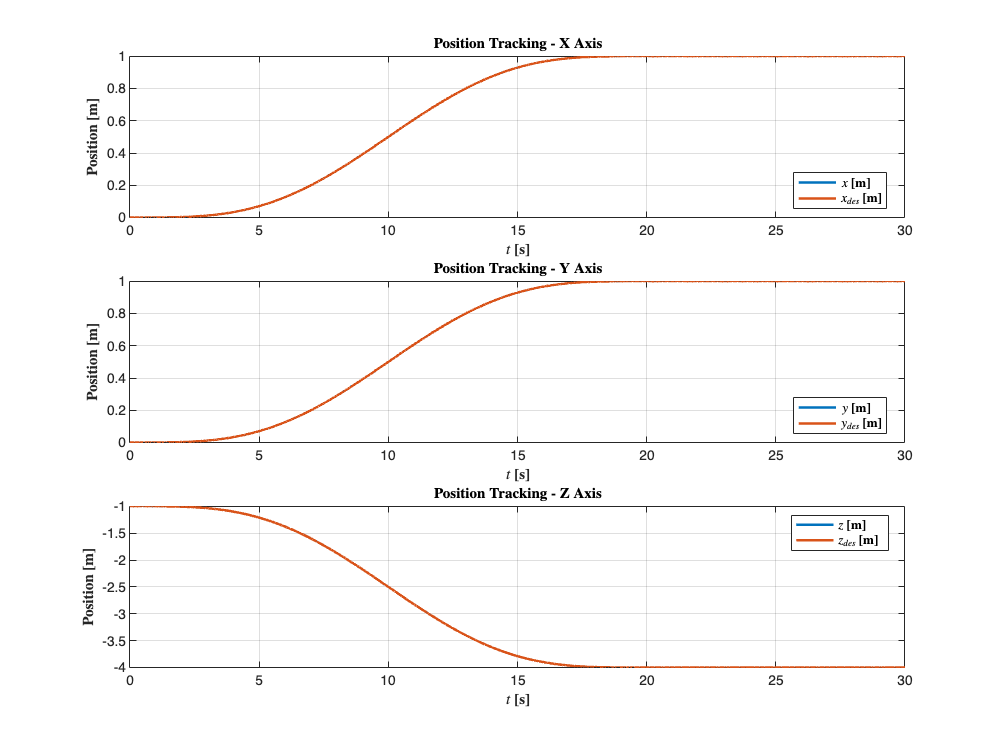

clear all;
close all;
clc;

modelName = 'geometric_control_template';

open_system(modelName);

% Simulation
simOut = sim(modelName);

t = simOut.x.time;  
err_R = simOut.err_R.signals.values;
u_T = simOut.u_T.signals.values;
err_w = simOut.err_w.signals.values;
x = simOut.x.signals.values;
y = simOut.y.signals.values;
z = simOut.z.signals.values;
x_des = simOut.x_des.signals.values;
y_des = simOut.y_des.signals.values;
z_des = simOut.z_des.signals.values;
err_p = simOut.err_p.signals.values;
dot_err_p = simOut.dot_err_p.signals.values;
tau_b = simOut.tau_b.signals.values;

% Plot parameters
fontSize = 11;
titleSize = 12;
legendSize = 10;
lineWidth = 2;

% Figure 1: Position tracking (actual vs desired)
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, x, 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
hold on
plot(t, x_des, 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', lineWidth)
title('\textbf{Position Tracking - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{Position [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
legend('\textbf{$x$ [m]}', '\textbf{$x_{des}$ [m]}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, y, 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
hold on
plot(t, y_des, 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', lineWidth)
title('\textbf{Position Tracking - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{Position [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
legend('\textbf{$y$ [m]}', '\textbf{$y_{des}$ [m]}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, z, 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
hold on
plot(t, z_des, 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', lineWidth)
title('\textbf{Position Tracking - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{Position [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
legend('\textbf{$z$ [m]}', '\textbf{$z_{des}$ [m]}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);

saveas(gcf, 'position_tracking.eps', 'epsc');


% Figure 2: Position errors
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, err_p(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Position Error - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{px}$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, err_p(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Position Error - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{py}$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, err_p(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Position Error - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{pz}$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'position_errors.eps', 'epsc');

% Figure 3: Velocity errors
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, dot_err_p(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Velocity Error - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\dot{e}_{px}$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, dot_err_p(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Velocity Error - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\dot{e}_{py}$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, dot_err_p(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Velocity Error - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\dot{e}_{pz}$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'velocity_errors.eps', 'epsc');

% Figure 4: Attitude errors
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, err_R(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Rotational error in SO(3)}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{R,x}$}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, err_R(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
%title('\textbf{Rotational error in SO(3)}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{R,y}$}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, err_R(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
%title('\textbf{Rotational error in SO(3)}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{R,z}$}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'rotational_errors.eps', 'epsc');

% Figure 5: Angular velocity errors
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, err_w(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Angular Velocity Error - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{\omega,x}$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, err_w(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Angular Velocity Error - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{\omega,y}$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, err_w(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Angular Velocity Error - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{\omega,z}$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'angular_velocity_errors.eps', 'epsc');

% Figure 6: Control signals
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(4,1,1)
plot(t, u_T, 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Total Thrust}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$u_T$ [N]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(4,1,2)
plot(t, tau_b(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Torque - Roll Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\tau_{b,x}$ [Nm]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(4,1,3)
plot(t, tau_b(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Torque - Pitch Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\tau_{b,y}$ [Nm]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(4,1,4)
plot(t, tau_b(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Torque - Yaw Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\tau_{b,z}$ [Nm]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'control_signals.eps', 'epsc');